# **ACM 11 Homework 2 Part 2/2 (Spring 2024)**

## **Due Friday, April 26, 11:59pm Pacific Time, by upload to Canvas.**

You should read the problem set-up in this file and follow the instructions to write and test your code to solve the heat equation. **You should only start this part when you are satisfied that your code in Part 1 is correct! **. This part 2/2 of the assignment makes up 30 out of 100 points.

When you are done with both parts, zip all of your files needed to run the code into a single zip and upload to Canvas. Your final zip should include the following.

-  `ACM11_HW2_part1.mlx`

- `ACM11_HW2_part2.mlx`

- `getMatrix.m`

- `forwardEulerLinear.m`

- `backwardEulerLinear.m`

- `reference.mat` 

## **Problem 4: N = 20, varying timestep size effect on error and stability (20 points)**

In Part 1 of the homework we fixed $N=100$ and $K=1000$. In this problem, we will try using our solver on a much coarser grid, $N=20$, and look at how the solution accuracy changes as we vary the timestep size, using $\Delta t=\left\{1\text{e-}1,1\text{e-2},1\text{e-}3,1\text{e-}4\right\}$. To measure the effect of the timestep size on the error, we will compare your solutions to a reference solution for the interior points, ${\mathbf{u}}_{\textrm{ref}}$, that we have provided in `reference.mat. `This reference solution is for the 19 interior grid points for this problem, but computed with a timestep of $\Delta \;t_{\textrm{ref}} ={10}^{-5}$. Let $\mathbf{u}_K$ be the solution at the interior grid points at time $T$ calculated from our methods, and define the error as follows:


$$\text{err}=\sqrt{\Delta x}\cdot\|\mathbf{u}^{\text{true}, T}-\mathbf{u}_K\|_2\,,$$


where $\|\cdot\|_2$ is the Euclidean norm.  We will use the same $T=1$ and $\kappa =0\ldotp 02$ and $L=1$ as in Part 1.

**Problem 4a: error and timing plots**

In the block below, set up a computational grid for the N-1 interior points for $N=20$. Call your `getMatrix.m` function from Part 1 to get the matrix **A**, and compute the initial condition from part 1,

$u_{\rm init}(x)=\sin\left(\frac{\pi x}{L}\right) + 2\sin\left(\frac{2\pi x}{L}\right)+0.4\sin\left(\frac{11\pi x}{L}\right)$,

on your computational grid. Then, loop through the following timestep sizes: $\Delta t=\left\{1\text{e-}1,1\text{e-2},1\text{e-}3,1\text{e-}4\right\}$, and compute the solution at the final time $T=1$ using both your forward and backward Euler functions. For each of these solves, time each solve using the `tic/toc` commands and store the times required to solve, and compute the errors as defined above for each method and store these errors. Make the following plots:

(1) Plot all of your forward Euler solutions at the different timestep sizes on a single axis, together with the reference solution, using multiple line styles to make as many of the lines distinguishable as possible. 

(2) Do the same as above for the backward Euler. 

(3) Use a loglog scale to plot the error vs. timestep size for both methods. 

(4) Use a loglog scale to plot the solve time vs. timestep size for both methods.

Include figure titles, axis labels, and legends, and use different line styles when necessary so that as many lines as possible are visible. 

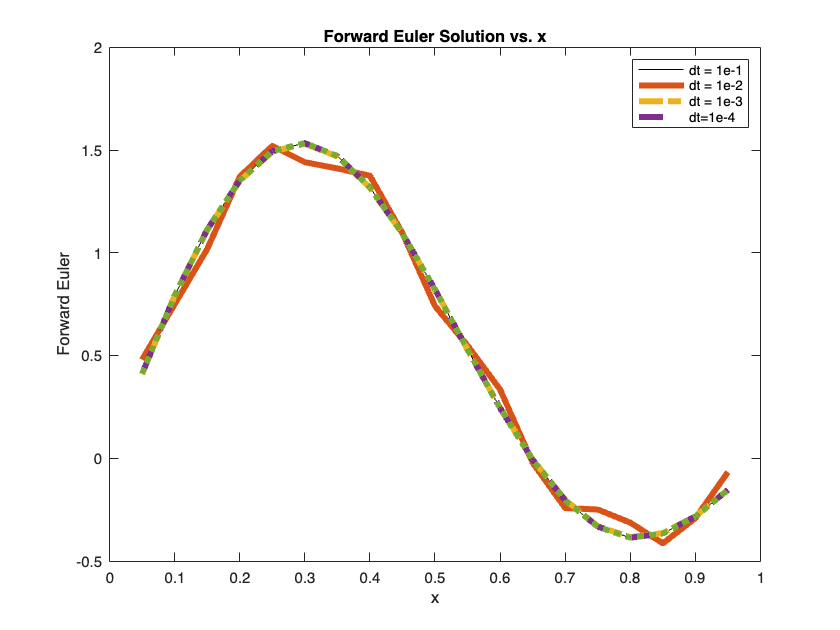

clear; close all

% here is a bunch of set-up for you
kappa = 0.02;
L = 1;
T = 1;
N = 20;
dx = 1/N;
dt_list = [1e-1 1e-2 1e-3 1e-4];
leg = {'dt = 1e-1', 'dt = 1e-2', 'dt = 1e-3', 'dt=1e-4'};

x = linspace(0,1,N+1);
x = x(2:end-1);
A = getMatrix(N,L);

u_init = sin(pi*x/L) + 2*sin(2*pi*x/L) + 0.4*sin(11*pi*x/L);
ux_true  = (-1)*pi*pi*sin(pi*x);

linestyles = {'-','-.','--',':'};   % you  might find this array of linestyles helpful

% load reference solution and initialize plots
load('reference.mat')

figure(1); clf
plot(x,p4_ref,'k'); hold on

figure(2); clf
plot(x,p4_ref,'k'); hold on

% pre-allocate space to store times/errors
[times,errors] = deal(zeros(length(dt_list),2));

% loop through times in dt_list
for i = 1:length(dt_list)
    dt = dt_list(i);
    
    % call forward Euler, time the solution, and compute the error.
    figure(1);
    tic;
    forwardSol = forwardEulerLinear(u_init', kappa, A, dt, T);
    timeF = toc;
    times(i, 1) = timeF;
    %ux_true = ux_true';
    errors(i, 1) = norm(p4_ref - forwardSol)*sqrt(dx);
    plot(x, forwardSol, 'LineStyle', linestyles{i}, 'LineWidth', 4);
    % call backward Euler, time the solution, and compute the error.
    % also plot the solution on the figure 2 axes
    figure(2);
    tic;
    backSol = backwardEulerLinear(u_init, kappa, A, dt, T);
    timeB = toc;
    times(i, 2) = timeB;
    errors(i, 2) = norm(p4_ref - backSol)*sqrt(dx);
    plot(x, backSol, 'LineStyle',linestyles{i}, 'LineWidth', 4);
   
end

figure(1);
% add title, legend, axes labels
xlabel('x');
ylabel('Forward Euler');
title('Forward Euler Solution vs. x');
legend(leg);

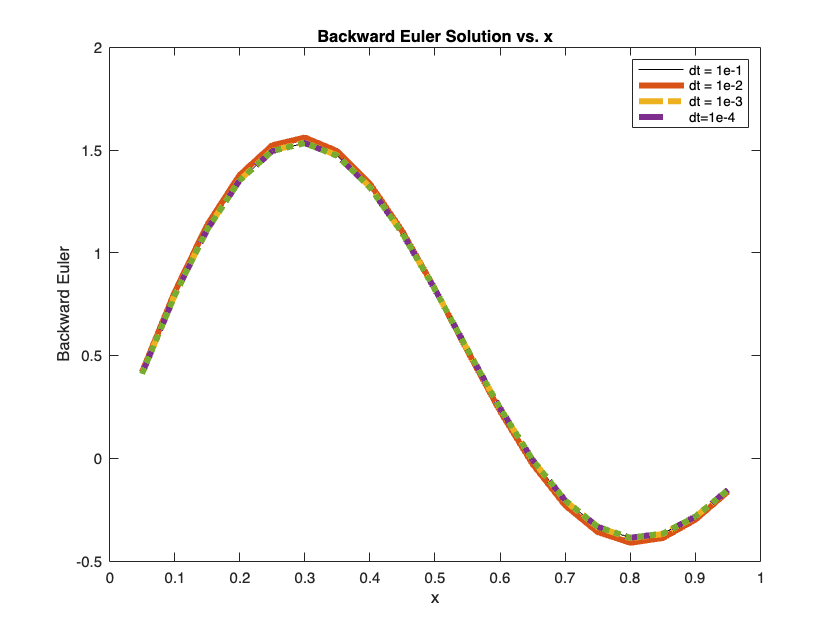



figure(2);
% add title, legend, axes labels
xlabel('x');
ylabel('Backward Euler');
title('Backward Euler Solution vs. x');
legend(leg);



figure(3); clf
% plot loglog of times vs. dt for both methods, include title, legend, axes
% labels
loglog(dt_list, times(:,1), 'LineStyle',linestyles{3});
hold;

Current plot held


loglog(dt_list, times(:,2), 'LineStyle',linestyles{2});
hold;

Current plot released


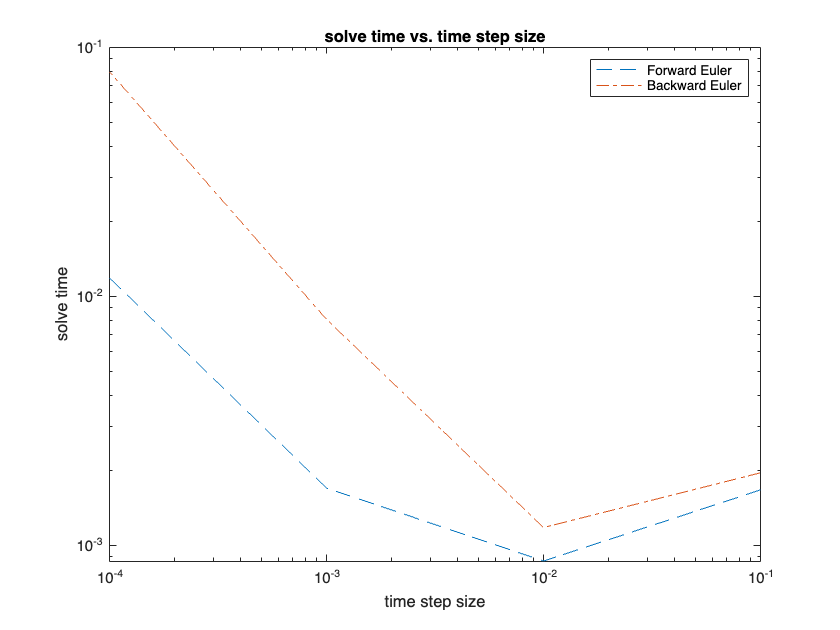

xlabel('time step size');
ylabel('solve time');
title('solve time vs. time step size');
legend('Forward Euler', 'Backward Euler');


figure(4); clf
% plot loglog of errors vs. dt for both methods, include title, legend, axes
% labels
loglog(dt_list, errors(:,1), 'LineStyle',linestyles{4});
hold;

Current plot held


loglog(dt_list, errors(:,2), 'LineStyle',linestyles{1});
hold;

Current plot released


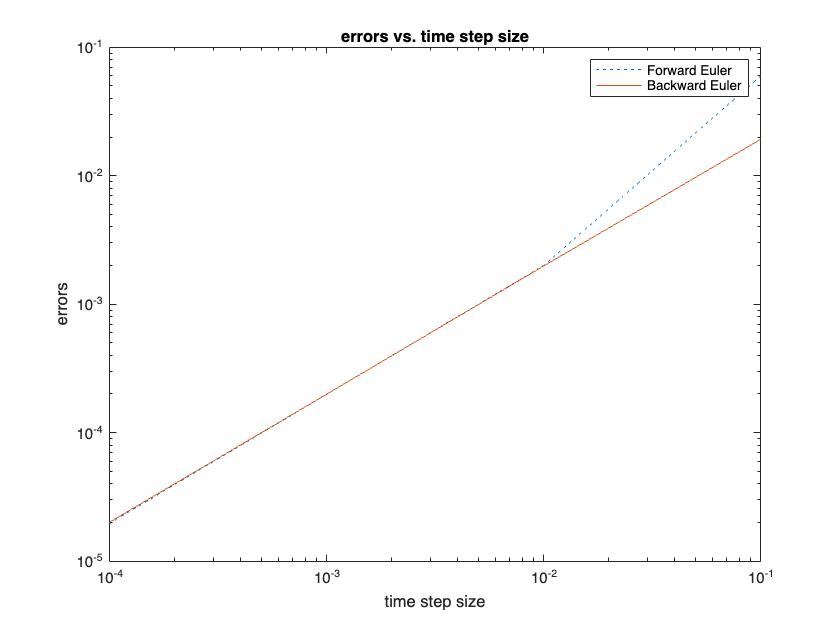

title('errors vs. time step size');
xlabel('time step size');
ylabel('errors');
legend('Forward Euler', 'Backward Euler');

**Problem 4b: N = 100, varying timestep size effect on error and stability**

Repeat problem 4a here, but this time using an interior grid of N-1 points for N = 100, and answer the discussion questions below. Most of the code you can copy over from 4a. You may want to limit the error plot y-axis to not plot above a $y_{\max } =1$ in order to more clearly see error trends. 

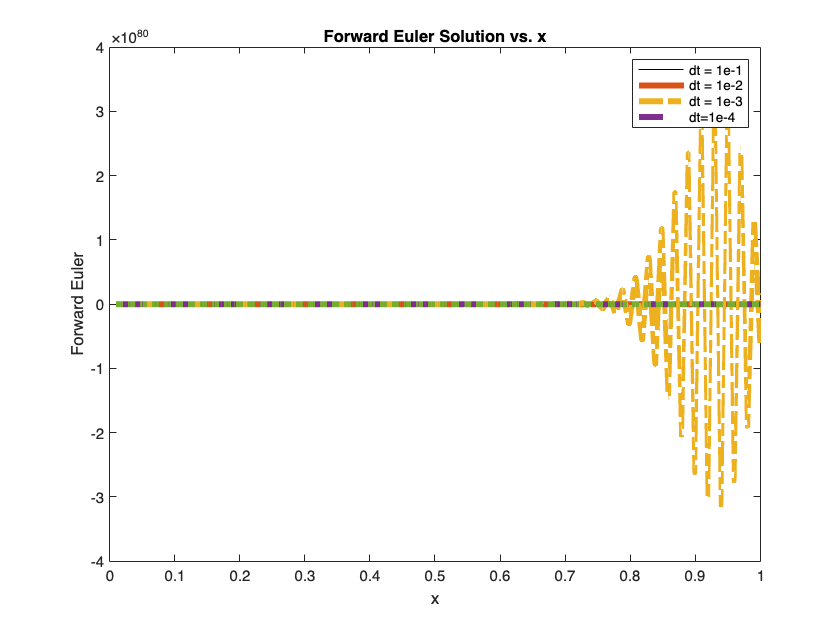

kappa = 0.02;
L = 1;
T = 1;
N = 100;
dx = 1/N;
dt_list = [1e-1 1e-2 1e-3 1e-4];
leg2 = {'dt = 1e-1', 'dt = 1e-2', 'dt = 1e-3', 'dt=1e-4'};

x = linspace(0,1,N);
x = x(2:end)';
A = getMatrix(N,L);

u_init = sin(pi*x/L) + 2*sin(2*pi*x/L) + 0.4*sin(11*pi*x/L);
ux_true  = (-1)*pi*pi*sin(pi*x);
linestyles = {'-','-.','--',':'};

% this is loaded from the reference file as well
figure(5); clf
plot(x,p5_ref,'k'); hold on

figure(6); clf
plot(x,p5_ref,'k'); hold on

% pre-allocate space to store times/errors
[times,errors] = deal(zeros(length(dt_list),2));

for i = 1:length(dt_list)
    dt = dt_list(i);

    % call forward Euler, time the solution, and compute the error.
    figure(5);
    tic;
    forwardSol = forwardEulerLinear(u_init, kappa, A, dt, T);
    timeF1 = toc;
    times(i, 1) = timeF1;
    errors(i, 1)  = norm(p5_ref - forwardSol)*sqrt(dx);
    plot(x, forwardSol, 'LineStyle', linestyles{i}, 'LineWidth', 4);


    % call backward Euler, time the solution, and compute the error.
    % also plot the solution on the figure 2 axes

    figure(6);

    tic;
    backSol = backwardEulerLinear(u_init', kappa, A, dt, T);
    timeB1 = toc;
    times(i, 2) = timeB1;
    errors(i, 2) = norm(p5_ref - backSol)*sqrt(dx);
    plotsB(i) = plot(x, backSol, 'LineStyle',linestyles{i}, 'LineWidth', 4);

end

figure(5);
% add title, legend, axes labels
xlabel('x');
ylabel('Forward Euler');
title('Forward Euler Solution vs. x');
legend(leg2);

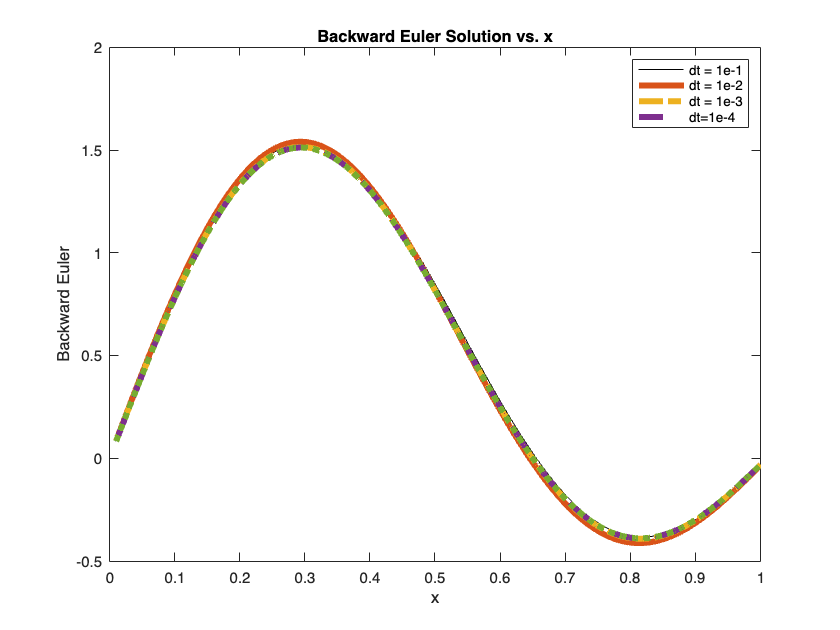


figure(6);
% add title, legend, axes labels
xlabel('x');
ylabel('Backward Euler');
title('Backward Euler Solution vs. x');
legend(leg2);


figure(7); clf
% plot loglog of times vs. dt for both methods, include title, legend, axes
% labels
loglog(dt_list, times(:,1), 'LineStyle',linestyles{3});
hold;

Current plot held


loglog(dt_list, times(:,2), 'LineStyle',linestyles{2});
hold;

Current plot released


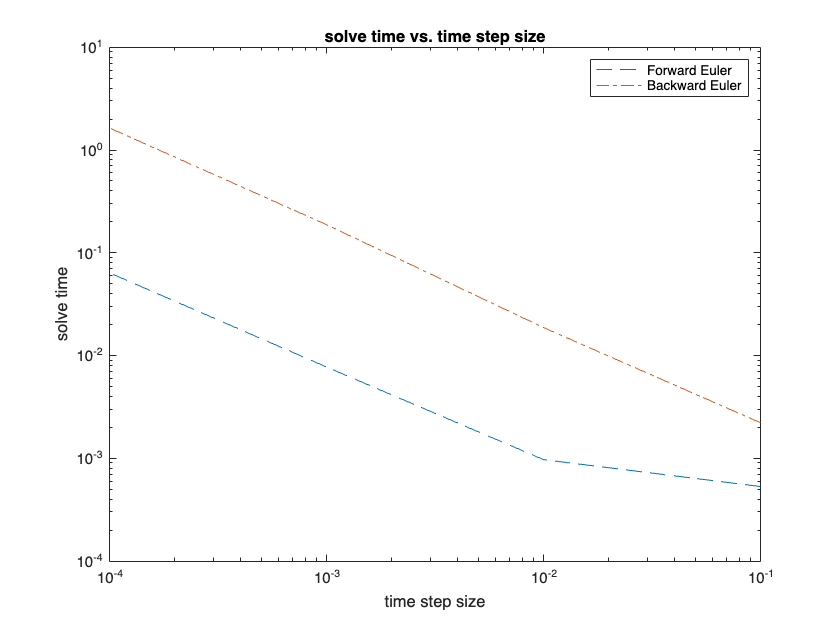

xlabel('time step size');
ylabel('solve time');
title('solve time vs. time step size');
legend('Forward Euler', 'Backward Euler');


figure(8); clf
% plot loglog of errors vs. dt for both methods, include title, legend, axes
% labels
loglog(dt_list, errors(:,1), 'LineStyle',linestyles{4});
hold;

Current plot held


loglog(dt_list, errors(:,2), 'LineStyle',linestyles{1});
hold;

Current plot released


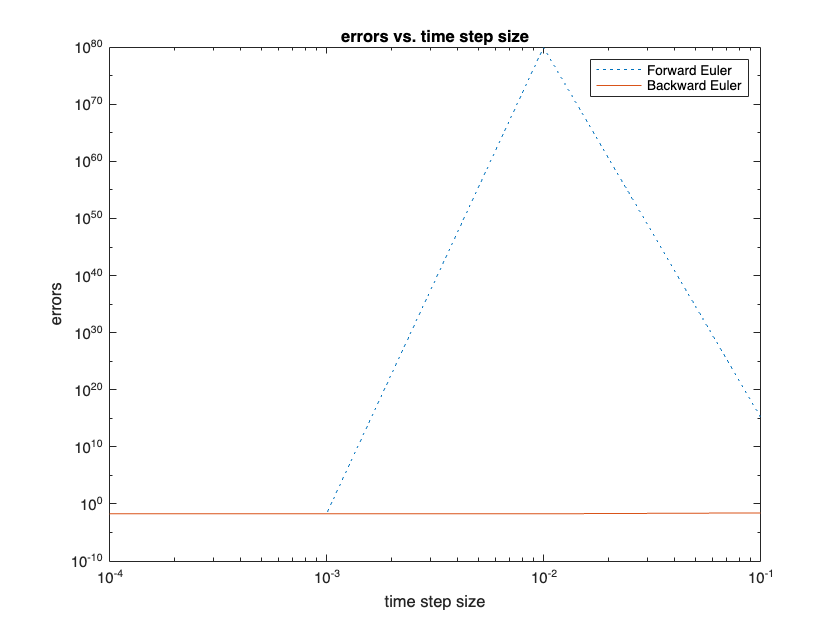

title('errors vs. time step size');
xlabel('time step size');
ylabel('errors');
legend('Forward Euler', 'Backward Euler');

**Problem 4c: Discussion**

Timing: which method is faster in general? How do the solve times of each method change as the timestep size is decreased? 

fprintf(['Forward Euler is faster in general, according to the plotted data of solve time vs time\n' ...
    'step size for the two methods. For N = 20, both forward and backward Euler have a sharp increase in time step size\n' ...
    'once the time step reaches about 10^-2. Before 10^-2, the solve time steadily decreases on the \n' ...
    'loglog plot. For the larger N value, only forward Euler has a slight increase in the solve time\n' ...
    'around 10^-2. Backward Euler steadily decreases on the log log plot of solve time versus time step size.'])

Forward Euler is faster in general, according to the plotted data of solve time vs time
step size for the two methods. For N = 20, both forward and backward Euler have a sharp increase in time step size
once the time step reaches about 10^-2. Before 10^-2, the solve time steadily decreases on the 
loglog plot. For the larger N value, only forward Euler has a slight increase in the solve time
around 10^-2. Backward Euler steadily decreases on the log log plot of solve time versus time step size.

Instability: A solution is unstable if it seems to blow up. This can happen at larger time-step sizes. At what time-steps, if any, do you observe instability for the forward Euler solver? for the backward Euler solver? Examine how this is this different between 4a and 4b. What does this say about how the timestep needs to change for stability as the grid spacing becomes smaller?

fprintf(['The forward Euler solver seems to be unstable at dt = 1e-3 for N = 100 \n,' ...
    'as the graph is drastically changing at each x value. However,\n' ...
    'there does not seem to be any unstable dt values for the backwards\n' ...
    'Euler solver. There is instability for the forward Euler solver when the\n' ...
    'grid spacing is smaller (N is larger). This means that the timestep should \n' ...
    'be larger to optimize for stability, as grid spacing becomes smaller.'])

The forward Euler solver seems to be unstable at dt = 1e-3 for N = 100 
,as the graph is drastically changing at each x value. However,
there does not seem to be any unstable dt values for the backwards
Euler solver. There is instability for the forward Euler solver when the
grid spacing is smaller (N is larger). This means that the timestep should 
be larger to optimize for stability, as grid spacing becomes smaller.

Error: For the time-step sizes for which the backward Euler and forward Euler methods are stable, how do their errors compare? When the timestep size is shrunk by a factor of 10, how much does the error decrease? What does this say about the order of accuracy of the two ODE solvers?

fprintf(['For the stable time-step sizes for the forward and backward Euler, \n' ...
    'the error for the backward Euler solver is much less when N is large. When \n' ...
    'N is smaller, the forwards and backwards Euler solver have about the same error, \n' ...
    'but the forward Euler solver error increases more than the backwards \n ' ...
    'Euler solver around a time step size of 10^-2. When the timestep size is \n' ...
    'shrunk by a factor of 10, the error also shrinks by a factor of 10, indicating \n' ...
    'that both forwards and backwards Euler are first order. When N is large, forwards \n' ...
    'Euler has much more error after the timestep size increases from 10^-3.'])

For the stable time-step sizes for the forward and backward Euler, 
the error for the backward Euler solver is much less when N is large. When 
N is smaller, the forwards and backwards Euler solver have about the same error, 
but the forward Euler solver error increases more than the backwards 
 Euler solver around a time step size of 10^-2. When the timestep size is 
shrunk by a factor of 10, the error also shrinks by a factor of 10, indicating 
that both forwards and backwards Euler are first order. When N is large, forwards 
Euler has much more error after the timestep size increases from 10^-3.

### Problem 5: Linear Algebra Truths (4 points)

For each of the following statements, determine whether they are **true** or **false**. Please make sure to briefly justify each of the choices.

- One can compute the Cholesky factorization for any general matrix $A$.

False - The Cholesky factorizations can only be computed for symmetric positive definite matrices, not for any general matrix. 

- Any sparse matrix $A$ will have an $\mathcal{O}(N)$ complexity for finding the solution of $Ax = b$.

False - There are some algorithms with time complexity O(N) for certain kinds of sparse matrices, like the diagonal algorithm for diagonal matrices, and the TDMA algorithm for tridiagonal matrices. However, this only applies to some sparse matrices, not any sparse matrix. 

- If a system $Ax = b$ has more than one solution, then so does the system $Ax = 0$.

True - The system Ax = 0 is the system Ax = b where b is the zero vector. Therefore, if Ax = b has multiple solutions, then so can Ax = 0. 

- An over-determined system of equations can still have a unique solution.

True - An overdetermined system of equations is a system with more equations than uknowns. An overdetermined system of equations can have a solution if some of the equations are independent, or if some of the equations are linear combinations of others in the system. For example: 2x = 2, x = 1 is an overdetermined system with a unique solution.

### Problem 6: Attractive Roots (6 points)

As we note in lecture $4$, Newton's method is sensitive to the initial guess. In particular, if there are roots that are close together, different guess may lead to Newton's method converging to different roots or not converging at all.

To characterize the sensitivity to the initial guess, we can use a method called **basins of attraction**, which are based on identifying the subset of the input space where our method converges to a given root.

For this problem, consider the function below. 


$$f(x) = x^3 - 6x^2 + 11x - 6$$


**Problem 6a**

The code below paritions the interval $[0,4]$ into points seperated by $\Delta x = 0.1$. The code runs  Newton's method using the code newton.m starting from each initial point with a tolerance of $\epsilon = 10^{-12}$ and maximum number of iterations of $10$ to determine which of the roots of $f(x)$ it converges to, if any. 

For each output of Newton's method, determine if it converged to one of the three roots for this function $x = 1,2,3$ or if it did not converge. You can save the corresponding points or initial conditions. Further, plot these points along the x-axis and color them based on the roots that Newton's method converges to, if any. You should use one color if Newton's method did not converge to one of these points.

% Set up array for initial conditions
dx = 0.1;
x_grid = 0:dx:4;
converged1 = [];
converged2 = [];
converged3 = [];
no_converge = [];
no_converge_points = {};

% Write function f and Jacobian
f = @(x) x.^3 - 6 .* x.^2 + 11 .* x - 6;
j_f = @(x) 3 * x^2 - 12 * x + 11;

% Iterate through grid points - complete this code
for i = 1:length(x_grid)
    
    % Determine final guess with tolerance eps
    eps = 10^(-12);
    xn = newton(f,j_f,x_grid(i),eps,10);
    xn = xn(end);

    % Check if method converged to one of the roots {1,2,3} or did not
    % converge - save indices for these initial conditions

    if (abs(xn - 1) <eps)
        converged1(end + 1) = x_grid(i);

    elseif (abs(xn - 2) <eps)
        converged2(end + 1) = x_grid(i);
    elseif (abs(xn - 3) <eps)
        converged3(end+1) = x_grid(i);
    else
        no_converge(end + 1) = x_grid(i);
        %no_converge_points{end + 1} = xn;
    end
    
end

x = linspace(min(x_grid), max(x_grid), 1000);
% Plot a function
figure
plot(x_grid,f(x_grid));
hold on



% Plot the points in x_grid with color based on which root 
% they converged to (if any) using Newton's method. The points
% associated with each color indicate the corresponding basin of 
% attraction for the particular root

plot(converged1, f(converged1), 'ro');
plot(converged2, f(converged2), 'bo');
plot(converged3, f(converged3), 'go');
plot(no_converge, f(no_converge), 'ko');
title("Basins of Attraction - Newton's Method");
legend('f(x)', 'basin of 1', 'basin of 2', 'basin of 3', 'invalid', 'Location', 'northwest');

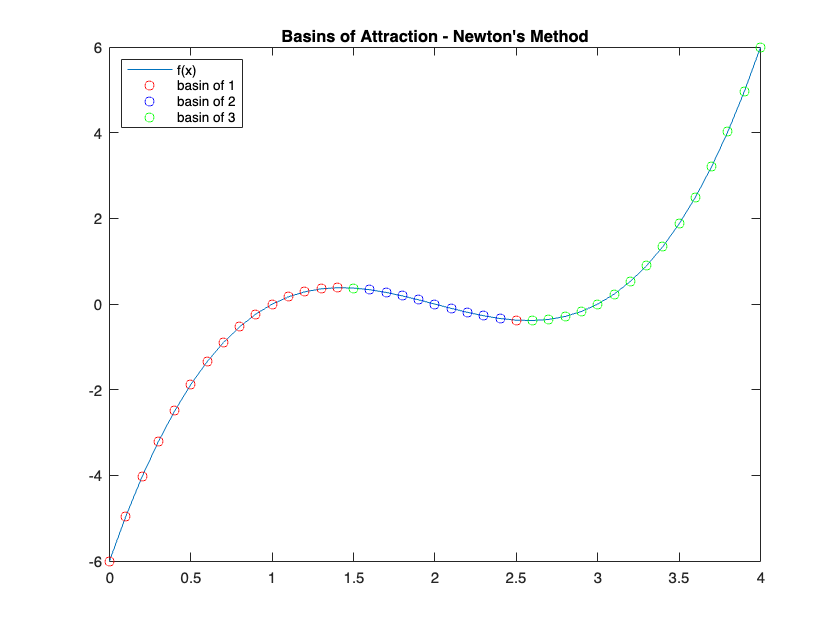

hold off

**Problem 6b:** **Hours**

How many hours did you spend on this homework, parts 1 and parts 2? Please round to the nearest half hour: 

hours = 8

hours = 8